# A few examples on how to use the Simscape battery models through code

**WMG, University of Warwick**

W.D. Widanage 19/09/2021 (The Pot)

## Ex 1: A 1C discharge - the "Hello World" of a battery model

## Ex 2: Applying a power profile

## Ex 3: Running several model instances with Simulink.SimulationInput

### Ex 3.1: Performing a Rate-test

### Ex 3.1: Compute Remaning Useful Energy and Time To Discharge maps

Calculate the Remaining Useful Energy (RUE) and Time to Discharge (TTD) of the cell as a function of different starting SoC, starting temperature and discharge power

clear, clc
simuLinkMdlStr = 'TECMD_Prototype'; % Specify the simulink file name (without the file extension)

nomE = 17.5;                   % Nominal cell energy [Wh] @ 25degC
Vmax = 4.2;                    % Set upper cut-off voltage 
Vmin = 2.5;                    % Set lower cut-off voltage for RUE/TTD

lowestSoC = 0.05;                               % Lowest starting SoC for RUE
highestSoC = 1;                                 % Highest starting SoC for RUE
nZ = 10;                                         % Number of SoC points
z0 = linspace(lowestSoC,highestSoC,nZ);         % Initial cell SoCs for RUE [-]

lowestPow = 10;                                 % Lowest discharge power
highestPow = 40;                                % Highest discharge power
nP = 6;                                         % Number of differnet input discarge power rates
P = -linspace(lowestPow,highestPow,nP);         % Discharge powers [W],negative for discharge

lowestAmbTemp = 10;                             % Lowest starting ambient temperature
highestAmbTemp = 40;                            % Lowest starting ambient temperature
nT = 3;                                         % Number of temperautre points
ambTemp = linspace(lowestAmbTemp,highestAmbTemp,nT) + 273;   % Ambient temperatures for RUE [K]

%% Parameters: Thermal
T0 = ambTemp;               % Initial cell temperature [K]


% Unit amplitude power time signal
timeVec = 0:10;
powVec = timeseries(ones(size(timeVec)),timeVec);

%% Simulate
open_system([simuLinkMdlStr,'.slx'],'loadonly');

cntr = 0;
for jj = 1:nT
    for ii = 1:nP  
        for zz = 1:nZ
            cntr = cntr + 1;

            %% Create a model SimulationInput object
            modelProp(cntr) = Simulink.SimulationInput(simuLinkMdlStr);

            % Set input
            ds = powVec*P(ii); ds.Name = "power";
            modelProp(cntr) = modelProp(cntr).setExternalInput('ds');
            modelProp(cntr) = modelProp(cntr).setVariable('ds',ds,'Workspace',simuLinkMdlStr);

            % Set TECMD initial conditions
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/Temperature Source'],'temperature',num2str(ambTemp(jj)));
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/TECMD'],'T0',num2str(T0(jj)));
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/TECMD'],'z0',num2str(z0(zz)));

            % Simulation run time
            modelProp(cntr) = modelProp(cntr).setModelParameter('StopTime','inf','SaveState','on','SaveOutput','on','SaveOperatingPoint','on', ...
                                                                'SaveFinalState','on','FinalStateName','OperPoint');
        end
    end
end

tic
simOut = parsim(modelProp,'TransferBaseWorkspaceVariables',"on","ShowProgress","on");

[20-Sep-2021 11:59:17] Checking for availability of parallel pool...
[20-Sep-2021 11:59:17] Starting Simulink on parallel workers...
[20-Sep-2021 11:59:17] Configuring simulation cache folder on parallel workers...
[20-Sep-2021 11:59:17] Transferring base workspace variables used in the model to parallel workers...
[20-Sep-2021 11:59:18] Loading model on parallel workers...
[20-Sep-2021 11:59:19] Running simulations...
[20-Sep-2021 11:59:21] Completed 1 of 180 simulation runs
[20-Sep-2021 11:59:21] Completed 2 of 180 simulation runs
[20-Sep-2021 11:59:21] Completed 3 of 180 simulation runs
[20-Sep-2021 11:59:22] Completed 4 of 180 simulation runs
[20-Sep-2021 11:59:22] Completed 5 of 180 simulation runs
[20-Sep-2021 11:59:22] Completed 6 of 180 simulation runs
[20-Sep-2021 11:59:23] Completed 7 of 180 simulation runs
[20-Sep-2021 11:59:23] Completed 8 of 180 simulation runs
[20-Sep-2021 11:59:24] Completed 9 of 180 simulation runs
[20-Sep-2021 11:59:24] Completed 10 of 180 simulation r

% simOut = sim(modelProp,"ShowProgress","on");



#### Calculate Time to Discharge (TTD) and RUE

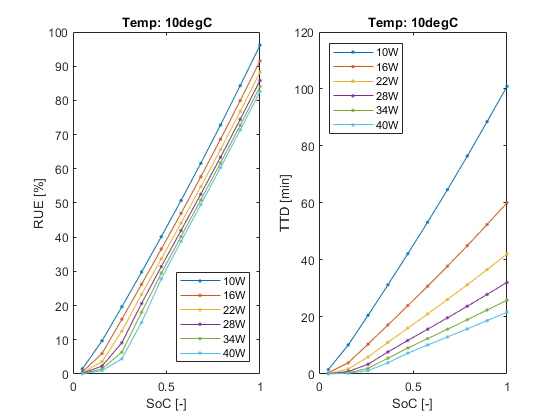

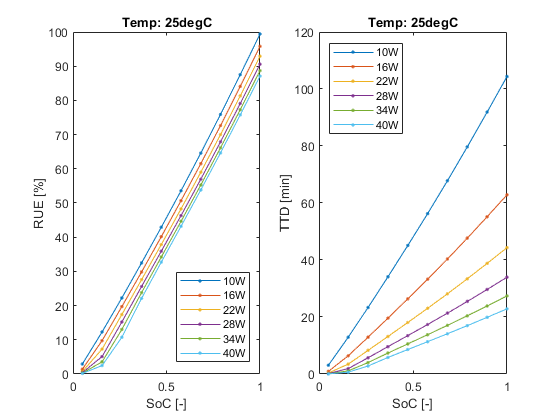

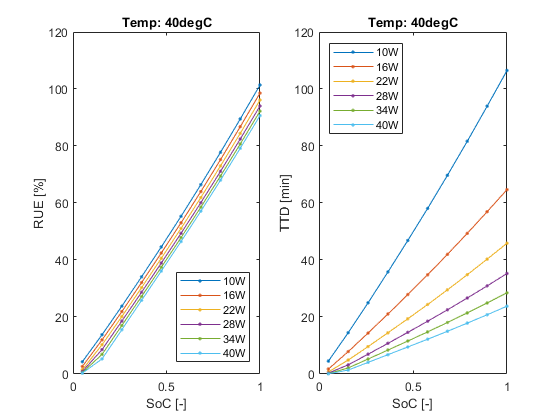

for ii = 1:cntr
    mdlCurr = find(simOut(ii).logsout,'I');
    mdlVol = find(simOut(ii).logsout,'V');
    appP = min(mdlCurr.Values.*mdlVol.Values);
    TTDVec(ii,1) = max(mdlCurr.Values.Time)/60; % time to discharge in minutes
    RUEVec(ii,1) = -appP(2) *TTDVec(ii)/60; % RUE in [Wh]
end
% Reshape tTD and RUE into nZ x nP x nT
TTD = reshape(TTDVec,nZ,nP,nT);
RUE = reshape(RUEVec,nZ,nP,nT)/nomE*100;        % Relative RUE

% Plot TTD and RUE vs SoC
for tt = 1:nT
    figure
    subplot(1,2,1)
    plot(z0,RUE(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('SoC [-]'); ylabel('RUE [%]'); legend(string(-P)+"W",'Location',"best")
    subplot(1,2,2)
    plot(z0,TTD(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('SoC [-]'); ylabel('TTD [min]'); legend(string(-P)+"W",'Location',"best")
end

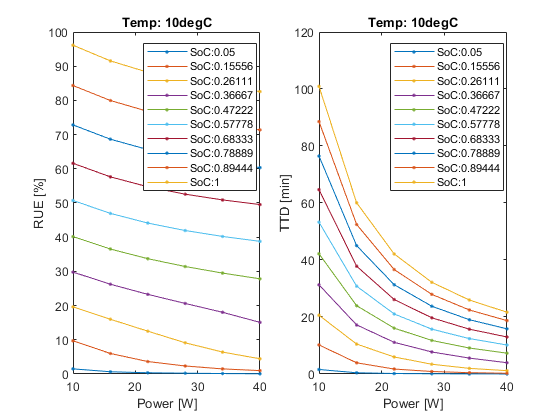

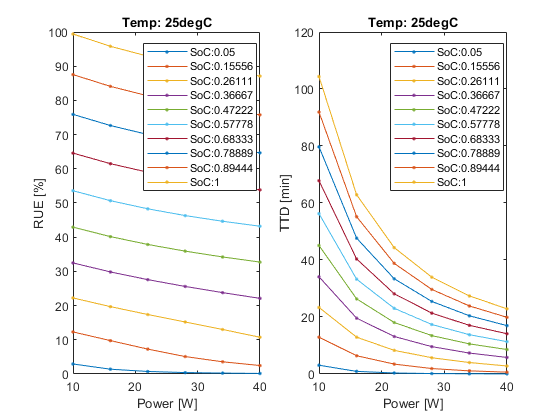

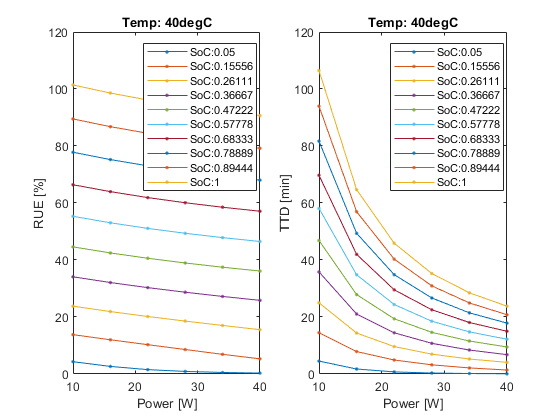


% Plot TTD and RUE vs power and temperature
RUE_P = permute(RUE,[2,1,3]);        % nP, nZ, nT
TTD_P = permute(TTD,[2,1,3]);        % nP, nZ, nT
for tt = 1:nT
    figure
    subplot(1,2,1)
    plot(-P,RUE_P(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('Power [W]'); ylabel('RUE [%]'); legend(["SoC:" + string(z0)],'Location',"best")
    subplot(1,2,2)
    plot(-P,TTD_P(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('Power [W]'); ylabel('TTD [min]'); legend(["SoC:" + string(z0)],'Location',"best")
end


close_system([simuLinkMdlStr,'.slx'],'loadonly')